# EE352 Automatic Control Assignment - Question 2

**Iterative Reduction of mm**

**Student Name:** PERERA J.D.T.

**Registration Number:** E/21/291

## 1. Define System Parameters

clc;
clear;
close all;

% Parameters (DOB: 2003-01-18)
yy = 3;
mm = 1;
dd = 18;
SE = 291; 

fprintf('Parameters: yy=%d, mm=%d, dd=%d, SE=%d\n', yy, mm, dd, SE);

Parameters: yy=3, mm=1, dd=18, SE=291


## Q2: Effect of Dampening (mm) reduction

We will reduce the value of $mm$ in 10 equal steps to zero.

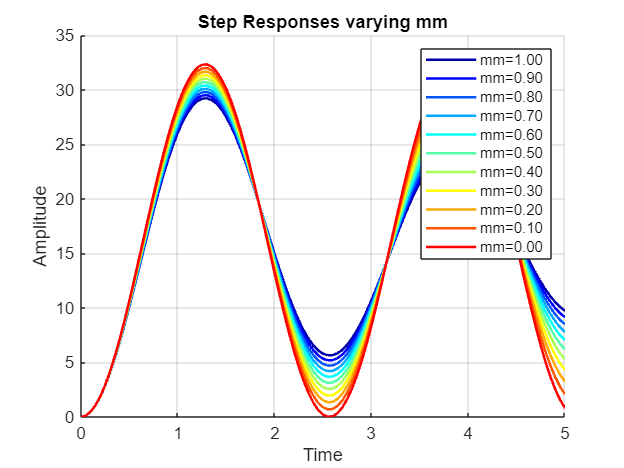

num = [SE];
mm_values = linspace(mm, 0, 11); % Range from mm down to 0

% Prepare Figures
fig_resp = figure('Name', 'Q2: Step Responses');
hold on; 
title('Step Responses varying mm'); 
xlabel('Time'); ylabel('Amplitude');

fig_poles = figure('Name', 'Q2: Pole Locations');
hold on; 
title('Pole Locations varying mm'); 
xlabel('Real Axis'); ylabel('Imaginary Axis');
grid on; xline(0,'k--'); yline(0,'k--');

colors = jet(length(mm_values));

% Iteration Loop
for i = 1:length(mm_values)
    curr_mm = mm_values(i);
    curr_den = [yy, curr_mm, dd];
    
    % Create temp TF
    G_temp = tf(num, curr_den);
    
    % Plot Step Response
    figure(fig_resp);
    [y, t] = step(G_temp, 5);
    plot(t, y, 'Color', colors(i,:), 'LineWidth', 1.5, ...
        'DisplayName', sprintf('mm=%.2f', curr_mm));
    
    % Plot Poles
    figure(fig_poles);
    p = roots(curr_den);
    plot(real(p), imag(p), 'x', 'Color', colors(i,:), 'LineWidth', 2, 'MarkerSize', 10, ...
        'DisplayName', sprintf('mm=%.2f', curr_mm));
end

figure(fig_resp); legend show; grid on;

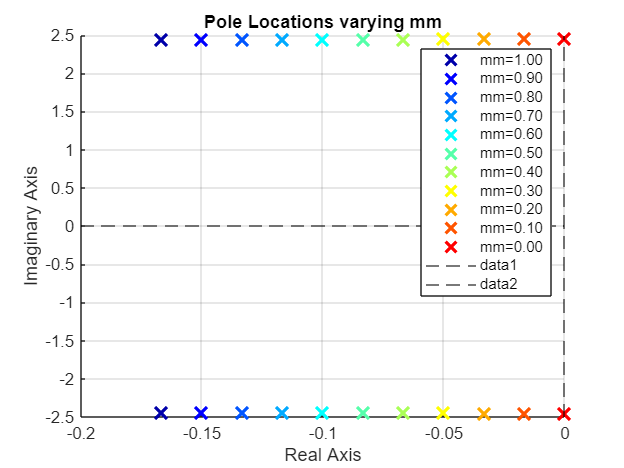

figure(fig_poles); legend show;

## Q2c: Explanation of Result for mm = 0

**Observation:**

As $mm$ decreases, the damping ratio $\zeta$ of the system decreases. The system becomes more oscillatory (higher overshoot).

At mm = 0: The denominator becomes $yy \cdot s^2 + dd$. The roots are at $s = \pm j\sqrt{dd/yy}$. Since the real part of the poles is zero, the system is undamped and marginally stable. The step response will exhibit sustained oscillations.